# Constructing (by hand) a transfer function from a step response

The first part of this script carries out the same steps as step002-open-loop-step-response/matlab/plotStepResponses.mlx.

## Read and plot the recorded data

The filename below belongs to the file with the step response experiment data. The step response data was recorded for input steps of +5 and -5 degrees. This value is fixed in the microcontroller code for the step response experiment, and it needs to be set here by hand. We also need to copy the time step (5ms= 0.005s) used in the arduino sketch. 

clear all;
close all; 
filename= "../../step002-open-loop-step-response/arduino/record_open_loop_step_response_data_for_matlab/data_for_matlab.txt"; 
uStep= 5; % deg, degrees
delta_t= 0.005; % seconds

We are now ready to read the data and to extract the time points and output values from it.

data = readtable(filename); 
tData = data{:, 1}'; % note transpose operator
yData = data{:, 2}';
t0= tData(1);
numpoints= length(yData);

We need to divide all time data by 1e6 to to convert microseconds to seconds. 

tData= tData* 1e-6; 

We first plot the entire set of recorded data, which contains more than one step response. 

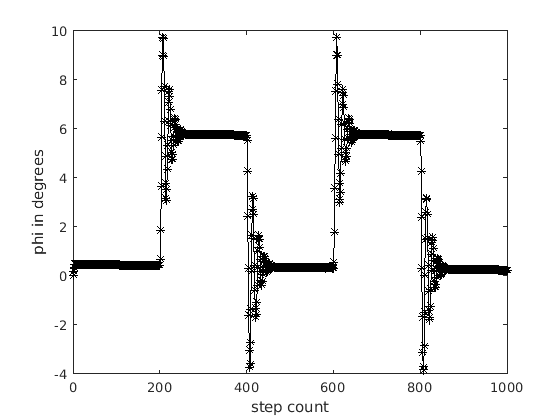

figure(); 
plot(yData, '-*', 'Color', 'black'); 
xlabel("step count");
ylabel("phi in degrees"); 

We now select a single step response to work with. Since the arduino generates a step input every 200 timesteps (which corresponds to a second for the sample time of 5ms), we can select steps 200 to 400. Actually, 200 to 300 suffice, since a new steady state has been reached after 100 steps. Play with these numbers to check if we picked a good interval. (Try 195 to 250, for example. Also try 199 to 250 and 201 to 250.)

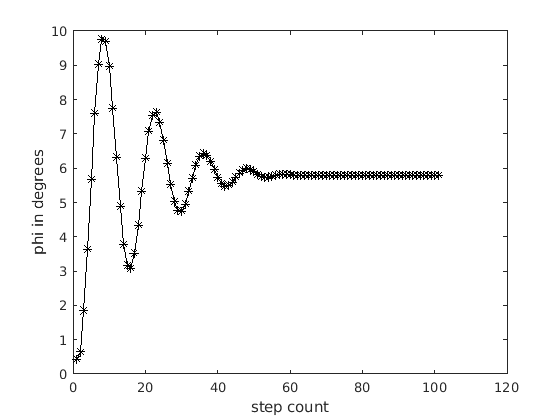

kstart= 200;
kstop= 300; 
figure();
plot(yData(kstart:kstop), '-*', 'Color', 'black'); 
xlabel("step count"); 
ylabel("phi in degrees"); 

Having selected an appropriate interval of steps, we can discard all other data. We can also reset the time of the first data point to be t=0s.

Let's also include the input signal for comparison.

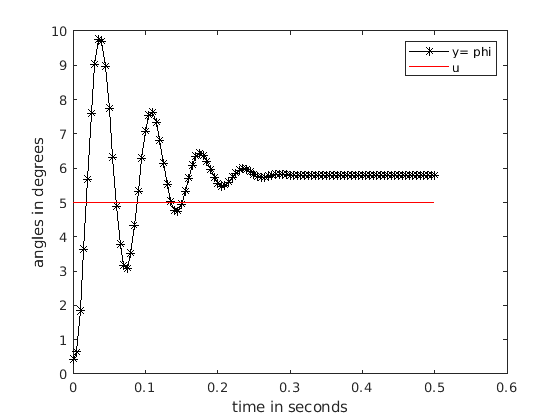

figure(); 
tData= tData(kstart:kstop)- tData(kstart); 
yData= yData(kstart:kstop); 
plot(tData, yData, '-*', 'Color', 'black');
hold on;
uData= uStep* ones(1, length(tData)); 
plot(tData, uData, '-', 'Color', 'red'); 
legend("y= phi", "u"); 
xlabel("time in seconds"); 
ylabel("angles in degrees"); 

Note that the $y$ may reach a new steady state value that is not equal to the input step. This must be accounted for with a static gain $K \ne 1$ in the transfer function. The output $y$ and input step may even have opposite signs, which can be accounted for by $K< 0$.

## Construct the transfer function 

The readme-file for the gimbal lab explains how to find the constants $y_\mathrm{inf}$, $y_\mathrm{max}$ and $t_\mathrm{rise}$ from the recorded step response. The steps required to find these constants are carried out below. Subsequently, the constants $\{{y_\mathrm{inf}, y_\mathrm{max}, t_\mathrm{rise}\}$are used to determine the constants $\{K, D, \omega_0\}$of the desired transfer function

$G(s)=\frac{K\omega_0^2}{s^2+ 2 K\omega_0 s + \omega_0^2}$.

Let's determine the parameters $y_\mathrm{inf}$, $y_\mathrm{max}$ and $t_\mathrm{rise}$ one by one.

### Finding the new steady state value $y_\textrm{inf}$

The new steady state value is approximately equal to the value of the output $y$ at the last time step plotted above. 

Note that we are collecting all transfer function data in 'tfData'. 

tfData.yinf= yData(end); % 'tfData' is short for transfer function data

Let's check this value by plotting it along with the step response.

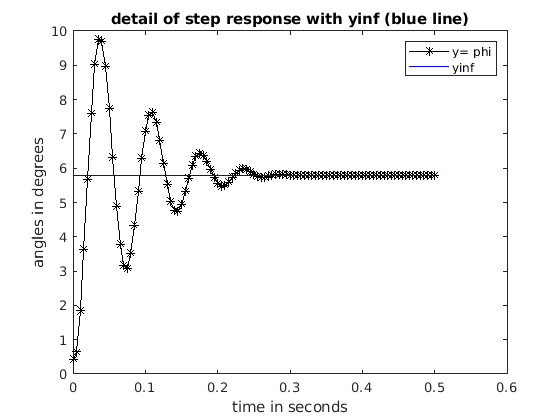

figure();
plot(tData, yData, '-*', 'Color', 'black');
hold on;
plot(tData, ones(1, length(tData))* tfData.yinf, '-', 'Color', 'blue'); 
legend("y= phi", "yinf"); 
xlabel("time in seconds"); 
ylabel("angles in degrees");
title("detail of step response with yinf (blue line)")

### Finding the rise time $t_\mathrm{rise}$ (rise time, Anregelzeit) and the maximum overshoot value $y_\mathrm{max}$

We focus on the first 0.1 seconds to find the rise time. 

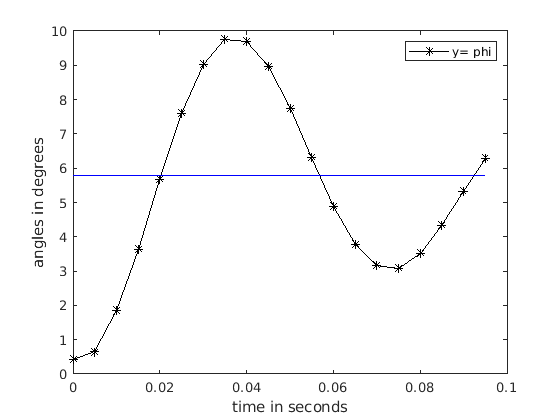

new_kstop= floor(length(tData)/5);

figure();
plot(tData(1:new_kstop), yData(1:new_kstop), '-*', 'Color', 'black');
hold on;
plot(tData(1:new_kstop), ones(1, new_kstop)* tfData.yinf, '-', 'Color', 'blue'); 
legend("y= phi"); 
xlabel("time in seconds"); 
ylabel("angles in degrees");

We can determine both the rise time $t_\mathrm{rise}$ and the maximum of the output $y_\mathrm{max}$from this plot. Let's read it off the plot and check it visually.

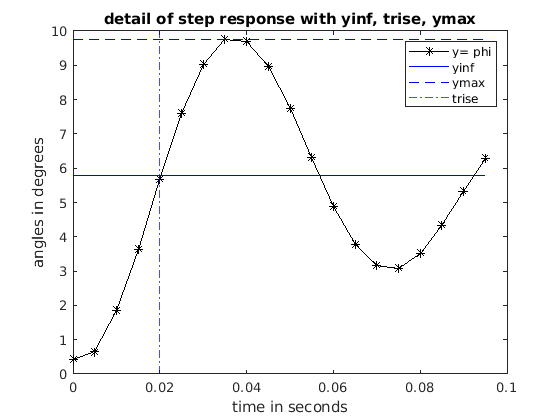

tfData.trise= 0.02; % seconds
tfData.ymax= yData(8); 

figure();
plot(tData(1:new_kstop), yData(1:new_kstop), '-*', 'Color', 'black');
hold on;
plot(tData(1:new_kstop), ones(1, new_kstop)* tfData.yinf, '-', 'Color', 'blue'); % blue line for K
plot(tData(1:new_kstop), ones(1, new_kstop)* tfData.ymax, '--', 'Color', 'blue'); 
xline(tfData.trise, '-.', 'Color', 'blue'); 
legend("y= phi", "yinf", "ymax", "trise"); 
xlabel("time in seconds"); 
ylabel("angles in degrees");
title("detail of step response with yinf, trise, ymax"); 

### Calculate the transfer function from $y_\mathrm{inf}$, $t_\mathrm{rise}$ and $y_\mathrm{max}$

Having collected the steady state gain $K$, the rise time $t_\mathrm{rise}$ and the maximum output value $y_\mathrm{max}$, we can determine an approximate 2nd-order transfer function for our recorded data.

tfData.K= tfData.yinf/uStep; 
tfData.delta_ymax= (tfData.ymax- tfData.yinf)/tfData.yinf; 
tfData.D= 1/sqrt(1+(pi/log(tfData.delta_ymax))^2); 
tfData.omega0= (pi-acos(tfData.D))/tfData.trise/sqrt(1-tfData.D)^2; 

G= tf([tfData.K], [1/tfData.omega0^2 2*tfData.D/ tfData.omega0 1]);

## Compare the transfer function determined from data to the recorded data

We use matlab's "step" command to plot the step response of our transfer function $G$ for an input step `uStep` for this purpose. We then plot the original data in the same plot for comparison.

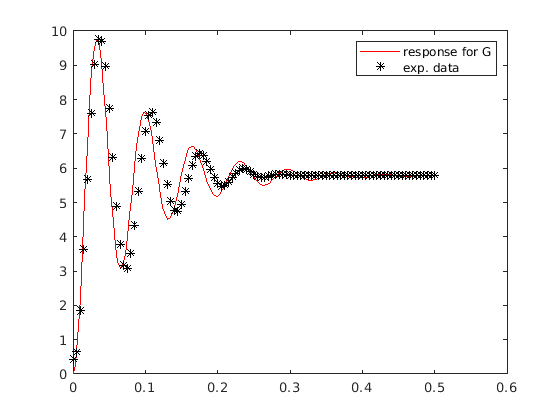

figure();
%theStepOptions= stepDataOptions('StepAmplitude',uStep);
[ySim, tSim, ~]= step(G, tData(end)); 
plot(tSim, uStep* ySim, '-', 'Color', 'red'); 
hold on; 
plot(tData, yData, '*', 'Color', 'black');
legend('response for G', 'exp. data'); 